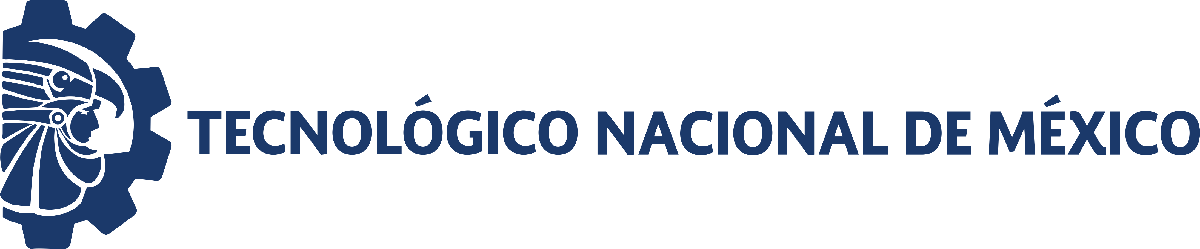                                 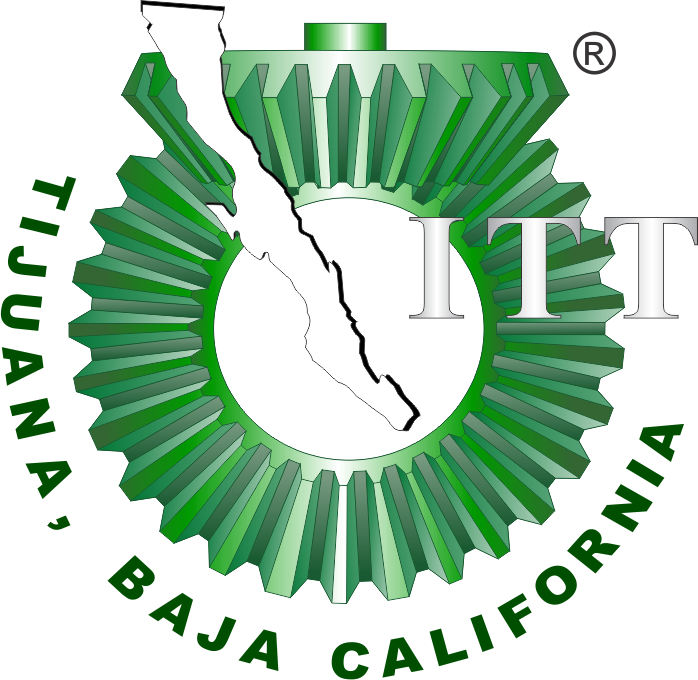

# Práctica 2: Sistema Respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

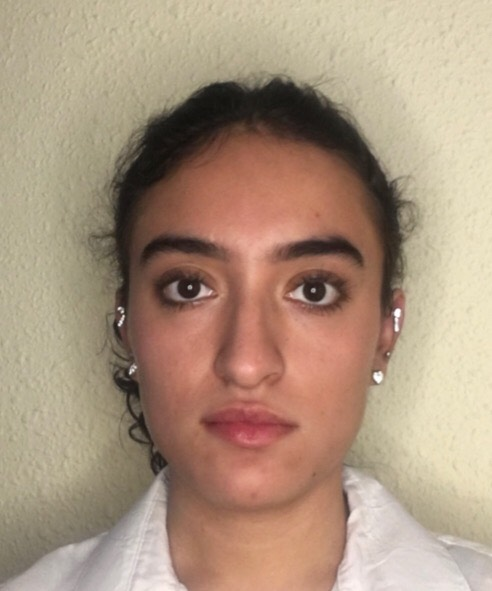

Nombre del alumno: Miroslava Jacobo Mendoza

Número de control: 21212669

Correo institucional: l21212669**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = "30";
file = "sysp2";
open_system (file);
parameters.StopTime = tend;
parameters.Solver = "ode15s";
parameters.MaxStep = "1E-3";
Controlador = "PID";

## Rendimiento del controlador

`kP = 202.0334`

`kI = 3709.0206`

`kD = 1.0047`

`Settling time = 0.0998 seconds`

`Overshoot = 7.02%`

`Peak = 1.07`

## Respiración normal 

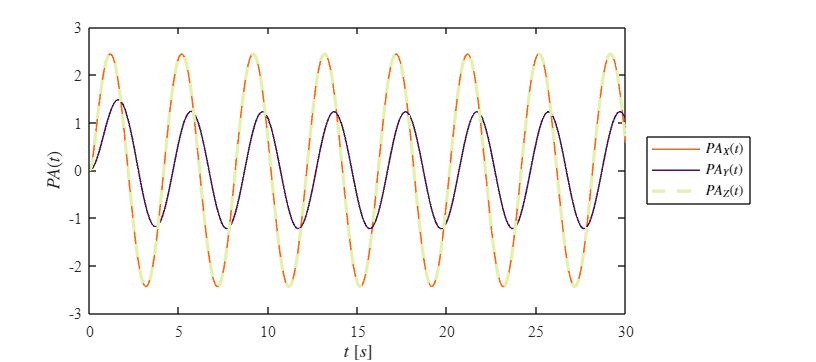

Signal = 'Respiración normal';
set_param('sysp2/Pao(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t, x1.PAx, x1.PAy, x1.PAz, Signal)

## Respiración enferma 

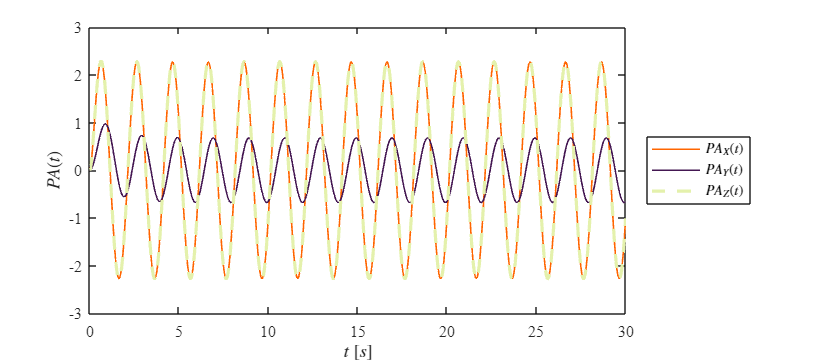

Signal = 'Respiración enferma';
set_param('sysp2/Pao(t)','sw','0');
x2 = sim(file,parameters);
plotsignals(x2.t, x2.PAx, x2.PAy, x2.PAz, Signal)

## Funcion: Respuesta a las senales

function plotsignals(t, PAx, PAy, PAz, Signal)

    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(10,'points')
    
    %rosa = [255/255, 116/255, 139/255];
    naranja = [255/255, 101/255, 0/255];
    verde = [228/255, 241/255, 172/255];
    morado = [68/255, 23/255, 82/255];

    hold on; grid off, box on;

    %plot (t, Pao, 'LineWidth', 1, 'Color', rosa)
    plot (t, PAx, 'LineWidth', 1, 'Color', naranja)
    plot (t, PAy, 'LineWidth', 1, 'Color', morado)
    plot (t, PAz, 'LineWidth', 2, 'Color', verde, 'LineStyle', '--')

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
    ylabel('$PA(t)$', 'Interpreter', 'Latex')
    
    L = legend("$PA_{X}(t)$","$PA_{Y}(t)$","$PA_{Z}(t)$");
    set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")
    
    if Signal == "Respiracion normal"
        xlim([-0.1, 30]); xticks(0:5:30)
        ylim([-2.5,2.5]); yticks(-2.5:0.5:2.5)

    elseif Signal == "Respiracion enfermo"
        xlim([-0.1, 30]); xticks(0:5:30)
        ylim([-1.5,1.5]); yticks(-1.5:0.5:1.5)
    end
    %exportgraphics (gcf, [Signal,'.pdf'], 'ContentType', 'Vector')
end